FM调制系统的软件实现

待处理信号

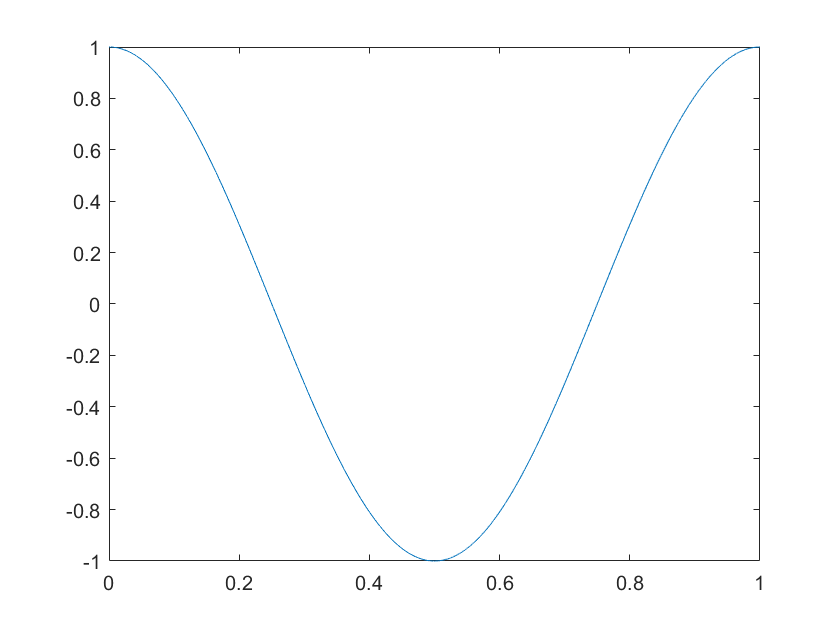

fs = 10000;
t = 0:1/fs:1;
message = cos(2*pi*t);
plot(t, message);

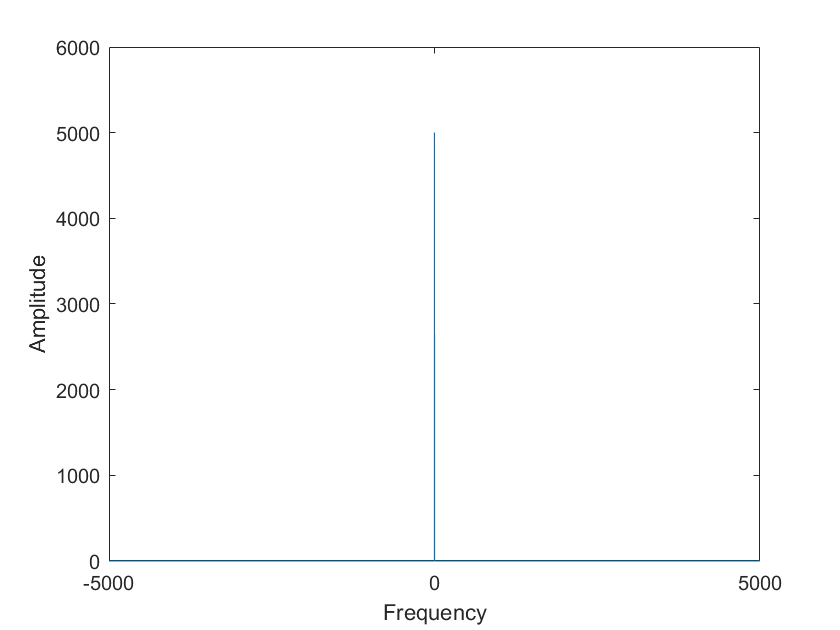

plotF(message, fs);

调制

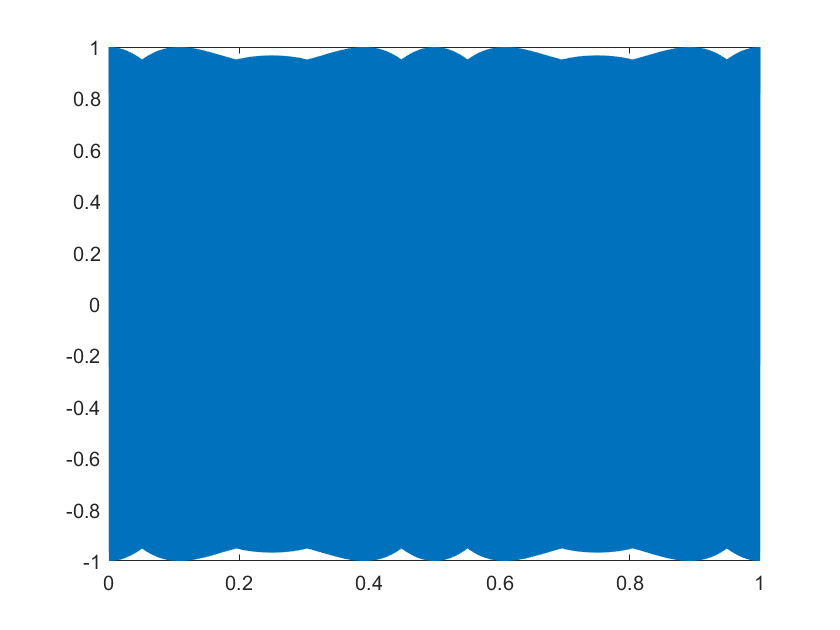

kf = 1;
Ac = 1;
m = cumtrapz(t, message);
modulated = Ac * cos(2*pi*1000*t + 2*pi*kf*m);
plot(t, modulated);

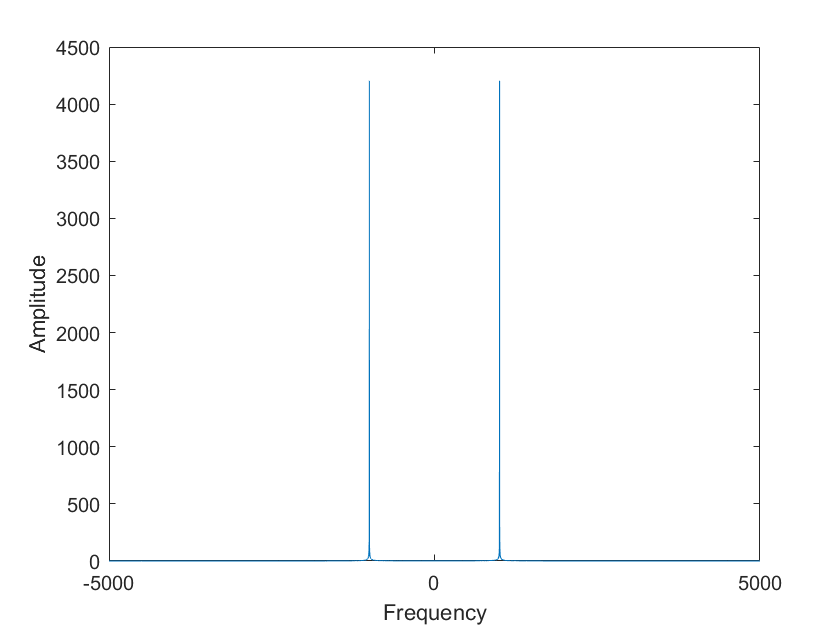

plotF(modulated, fs);

信道

sig_in_channel = modulated;

解调

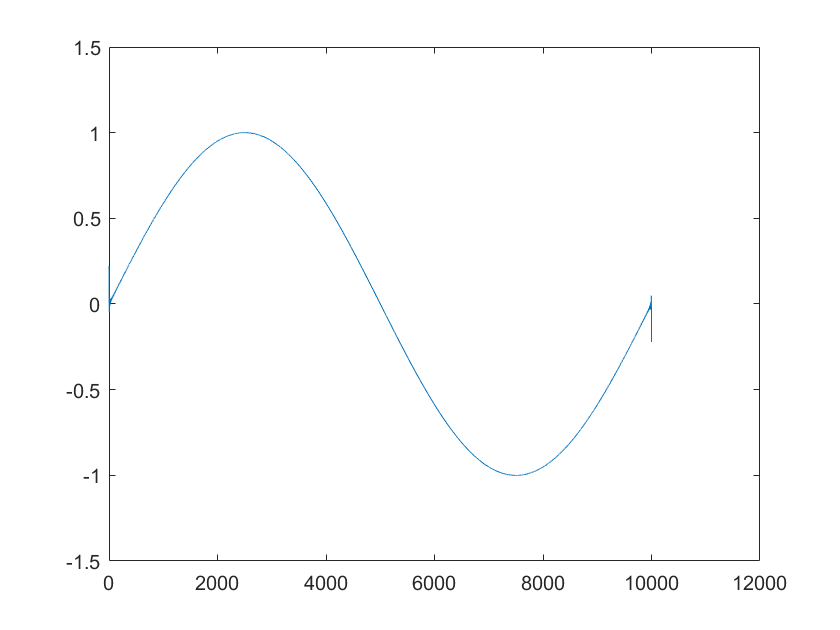

sig_hilbert = hilbert(sig_in_channel);
phase = unwrap(angle(sig_hilbert)) - 2*pi*1000*t;
f = phase / kf;
plot(f)

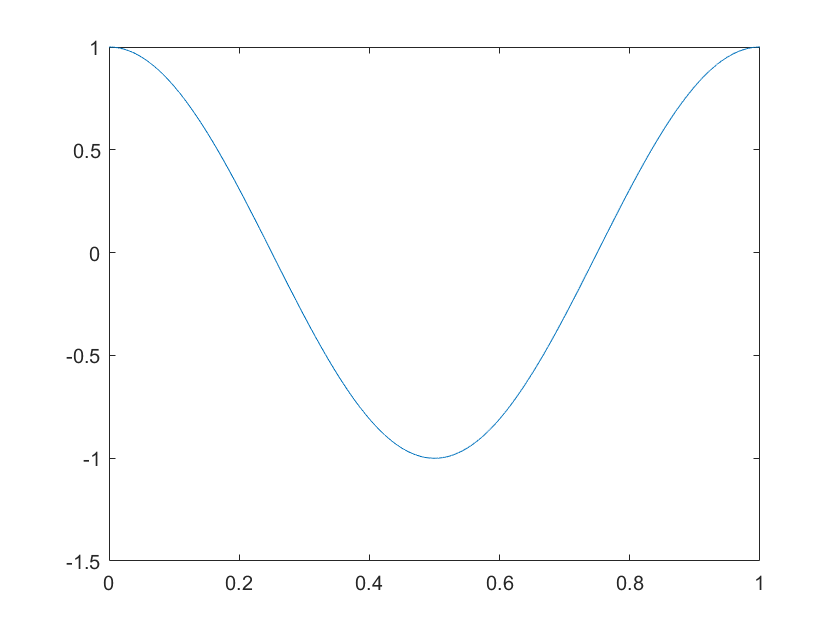

a = cumtrapz(t, f) * (-2*pi);
out = a - mean(a);
plot(t, out)